## Proyecto 1 - Probabilidad y estadística

### Nicolas Vargas Flores 1001368855

### **Jader Stalyn Chingal  1085948736**

#### Universidad de Antioquia 2024

datos = readtable("nutrition_elderly.csv");

### Parte 1 - Procedimiento

- **Conjunto de datos: nutrition_elderly**

        **a) ¿Cuál es la población bajo estudio?**

generos = datos.gender == 1; % Esto da como resultado un logical array

hombres = 0;
mujeres = 0;

for i = 1:length(generos)
    if generos(i) == 1
        hombres = hombres + 1;
    else
        mujeres = mujeres + 1;
    end
end

hombres % Total de hombres

hombres = 85

mujeres % Total de mujeres

mujeres = 141

total_muestra = hombres + mujeres

total_muestra = 226


edades = datos.age; % Esto da como resultado un array con las edades
min_edad = min(edades)

min_edad = 65

max_edad = max(edades)

max_edad = 91

La población corresponde a personas adultas mayores entres los 65 y 91 años a los cuales se les hizo un seguimiento nutricional.

       ** b) ¿La anterior información corresponde a una población o a una muestra?**

La anterior información corresponde a una muestra. Específicamente es una muestra de 85 hombres y 141 mujeres para un total de 226 personas mayores involucradas en el estudio.

        **c) ¿Cuántas variables hay en el conjunto de datos?**

variables_cantidad = length(datos.Properties.VariableNames)

variables_cantidad = 13

En este estudio se contemplaron 13 variables diferentes.

        **d)  Realice una tabla con los tipos de características que tiene cada dataset.**

variables = datos.Properties.VariableNames;
tipos = varfun(@class, datos, 'OutputFormat', 'cell');

tabla_tipos = table(variables', tipos', ...
                    'VariableNames', {'NombreVariable', 'Tipo'});

`varfun(@class,datos,'OutputFormat','cell')` aplica la función `class` a cada variable en la tabla `datos` y devuelve los tipos de datos en una celda

Observe que la tabla de los tipos de característica de este dataset son todo datos tipo ***double, ***este tipo de datos hace referencia a los ***double precision*** que son números de alta precisión; numeros flotantes, también conocidos como ***floats*** o decimales

Lo anterior tiene coherencia pues las respuestas de todos los participantes del estudio se almacenaron como números que van del 0 al 5, cantidade (kg, numero de tazas, cm, años) u opciones binarias entre 1 y 2.

- **Conjunto de datos: Fair's Extramarital Affairs Data**

datos1 = readtable("Affairs.csv");
num_sujetos = size(datos1, 1) 

num_sujetos = 601

genero_numeric = cellfun(@(x) strcmp(x, 'male'), datos1.gender); % 1 para Masculino, 0 para Femenino
% Calcular la tabla de frecuencias
frecuencia_masculino = sum(genero_numeric);
frecuencia_femenino = sum(~genero_numeric);

% Crear la tabla de frecuencias
tabla_frecuencias = [frecuencia_masculino; frecuencia_femenino];

% Visualizar la tabla de frecuencias
disp('Tabla de Frecuencias de Género:')

Tabla de Frecuencias de Género:


disp('--------------------------------')

--------------------------------


disp('Género    | Frecuencia')

Género    | Frecuencia


disp('----------------------')

----------------------


disp(['Masculino | ' num2str(frecuencia_masculino)])

Masculino | 286


disp(['Femenino  | ' num2str(frecuencia_femenino)])

Femenino  | 315


edades = datos1.age; % Esto da como resultado un array con las edades
mini_edad = min(edades)

mini_edad = 17.5000

maxi_edad = max(edades)

maxi_edad = 57

num_variables = size(datos1, 2)

num_variables = 10

**a) ¿Cuál es la población bajo estudio? **

La poblacion corresponde a personas en un rango de edad entre 20 y 55 años; aunque la edad no es tan precisa debido a que se registraron los datos con un valor pero este representa una desigualdad (17,5 = menos de 20 años) por tanto podria haber peronas menosres de 20 años y mayores a 55 años.

** b) ¿La anterior información corresponde a una población o a una muestra?**

La anterior información corresponde a una muestra. Específicamente es una muestra de 286 hombres y 315 mujeres para un total de 601 personas mayores involucradas en el estudio.

**c) ¿Cuántas variables hay en el conjunto de datos?**

En este estudio se contemplaron 10 variables diferentes.

**d)  Realice una tabla con los tipos de características que tiene cada dataset.**

% Obtener el nombre de las variables y el tipo de dato de cada una
nombres_variables = datos1.Properties.VariableNames;
tipos_de_dato = cell(size(nombres_variables));

for i = 1:numel(nombres_variables)
    tipos_de_dato{i} = class(datos1.(nombres_variables{i}));
end

% Crear la tabla con los nombres de las variables y los tipos de dato
tabla_tipos_de_caracteristica = table(nombres_variables', tipos_de_dato', 'VariableNames', {'Variable', 'Tipo de Característica'});

% Mostrar la tabla
disp(tabla_tipos_de_caracteristica);

        Variable         Tipo de Característica
    _________________    ______________________

    {'rownames'     }          {'double'}      
    {'affairs'      }          {'double'}      
    {'gender'       }          {'cell'  }      
    {'age'          }          {'double'}      
    {'yearsmarried' }          {'double'}      
    {'children'     }          {'cell'  }      
    {'religiousness'}          {'double'}      
    {'education'    }          {'double'}      
    {'occupation'   }          {'double'}      
    {'rating'       }          {'double'}      



Observe que la tabla de los tipos de característica de este dataset son todo datos tipo ***double,  *** a excepción de las variables gender y children que se representan como ***cell***. Los datos que  hacen referencia a los ***double precision***  son números de alta precisión; numeros flotantes, también conocidos como ***floats*** o decimales; por otra parte los datos que hace  referencia al tipo ***cell*** puede contener diferentes tipos de datos, incluyendo números, cadenas de caracteres, matrices, otras celdas, etc.

por tanto tiene sentido dado que todas las variables son de tipo numero a excpción de gender y children pues estsa son de tipo texto

### Parte 2 - Análisis descriptivo

- **Realizar las tablas de frecuencia de los datos a los que aplica y elija como presentar  los gráficos más apropiados según el tipo de variable.**

- **Resumir la información presente mediante tablas, gráficos adecuados y las medidas  de ubicación, dispersión y simetría para aquellas variables que aplique. Recuerde usar  gráficos de Histogramas, diagramas de cajas y bigotes, gráficos de dispersión.**

Se pueden responder las dos preguntas anteriores con lo siguiente:

**Tabla de frecuencias para la variable gender:**


Valores que toma la variable 


     1
     2



Frecuencia 


    85
   141



Frecuencia relativa (%) 


   37.6106
   62.3894



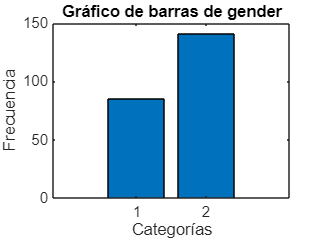

**Tabla de frecuencias para la variable situation:**


Valores que toma la variable 


     1
     2
     3



Frecuencia 


    98
   119
     9



Frecuencia relativa (%) 


   43.3628
   52.6549
    3.9823



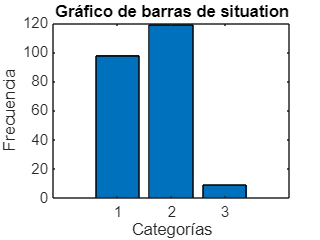

**Tabla de medidas de la variable tea:**


Valor mínimo de tea: 0


Valor máximo de tea: 10


Media de tea: 0.71239


Mediana de tea: 0


Desviación estándar de tea: 1.4488


Curtosis de tea: 14.8628


Asimetría de tea: 2.9525


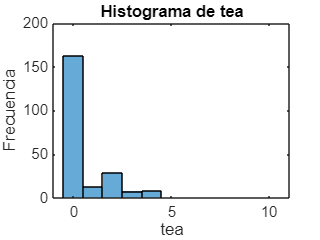

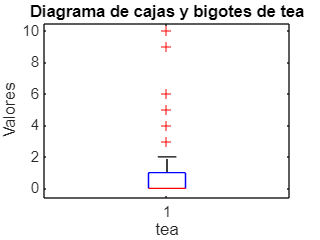

**Tabla de medidas de la variable coffee:**


Valor mínimo de coffee: 0


Valor máximo de coffee: 5


Media de coffee: 1.6195


Mediana de coffee: 2


Desviación estándar de coffee: 1.253


Curtosis de coffee: 2.924


Asimetría de coffee: 0.48847


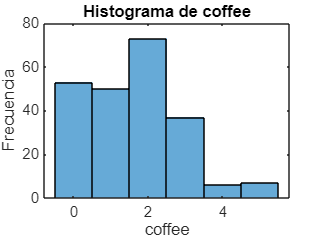

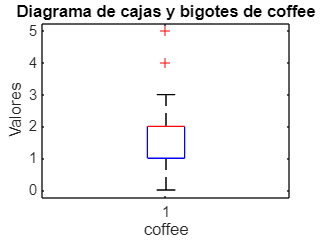

**Tabla de medidas de la variable height:**


Valor mínimo de height: 140


Valor máximo de height: 188


Media de height: 163.9602


Mediana de height: 163


Desviación estándar de height: 9.0034


Curtosis de height: 2.7782


Asimetría de height: 0.42562


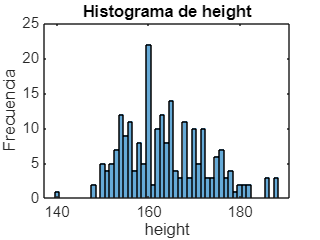

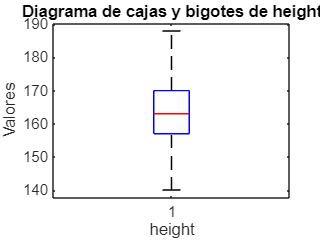

**Tabla de medidas de la variable weight:**


Valor mínimo de weight: 38


Valor máximo de weight: 96


Media de weight: 66.4823


Mediana de weight: 66


Desviación estándar de weight: 12.0334


Curtosis de weight: 2.5062


Asimetría de weight: 0.14639


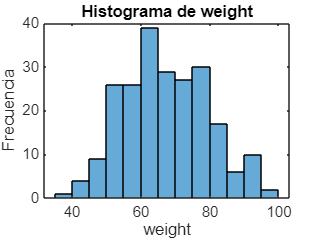

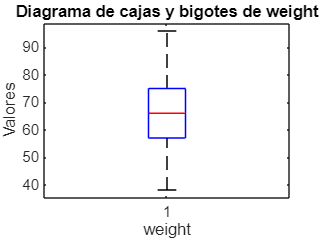

**Tabla de medidas de la variable age:**


Valor mínimo de age: 65


Valor máximo de age: 91


Media de age: 74.4779


Mediana de age: 74


Desviación estándar de age: 6.0053


Curtosis de age: 3.0017


Asimetría de age: 0.66909


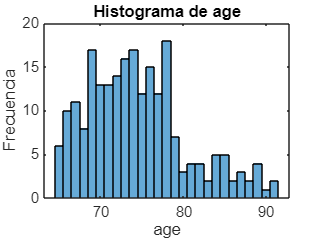

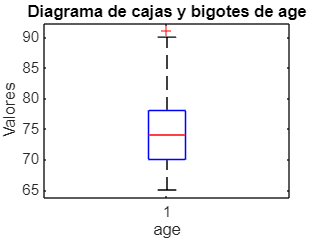

**Tabla de frecuencias para la variable meat:**


Valores que toma la variable 


     0
     1
     2
     3
     4
     5



Frecuencia 


     1
     3
    11
    83
    67
    61



Frecuencia relativa (%) 


    0.4425
    1.3274
    4.8673
   36.7257
   29.6460
   26.9912



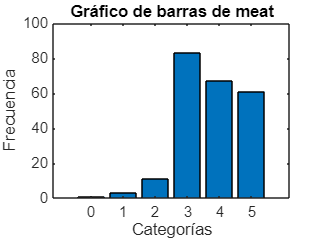

**Tabla de frecuencias para la variable fish:**


Valores que toma la variable 


     0
     1
     2
     3
     4
     5



Frecuencia 


     4
    21
    61
   118
    15
     7



Frecuencia relativa (%) 


    1.7699
    9.2920
   26.9912
   52.2124
    6.6372
    3.0973



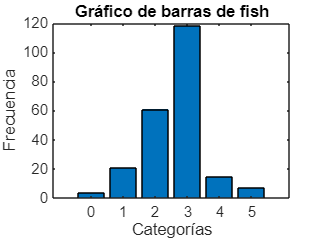

**Tabla de frecuencias para la variable raw_fruit:**


Valores que toma la variable 


     0
     1
     2
     3
     4
     5



Frecuencia 


     2
     8
     8
    14
    22
   172



Frecuencia relativa (%) 


    0.8850
    3.5398
    3.5398
    6.1947
    9.7345
   76.1062



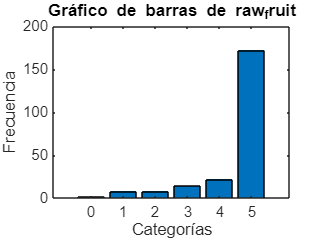

**Tabla de frecuencias para la variable cooked_fruit_veg:**


Valores que toma la variable 


     0
     1
     2
     3
     4
     5



Frecuencia 


     2
     3
     7
    30
    36
   148



Frecuencia relativa (%) 


    0.8850
    1.3274
    3.0973
   13.2743
   15.9292
   65.4867



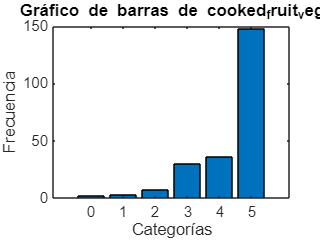

**Tabla de frecuencias para la variable chocol:**


Valores que toma la variable 


     0
     1
     2
     3
     4
     5



Frecuencia 


    50
    62
    16
    22
    11
    65



Frecuencia relativa (%) 


   22.1239
   27.4336
    7.0796
    9.7345
    4.8673
   28.7611



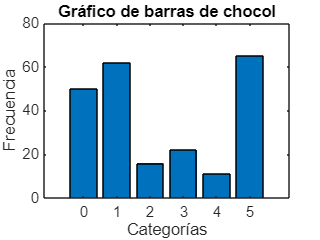

**Tabla de frecuencias para la variable fat:**


Valores que toma la variable 


     1
     2
     3
     4
     5
     6
     7
     8



Frecuencia 


    15
    27
    48
    68
    40
    23
     1
     4



Frecuencia relativa (%) 


    6.6372
   11.9469
   21.2389
   30.0885
   17.6991
   10.1770
    0.4425
    1.7699



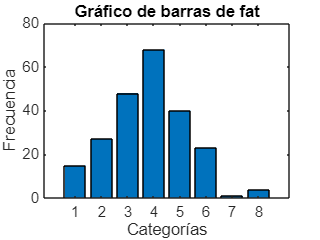

for i = 1:length(variables)
    if ismember(variables{i}, {'height', 'weight', 'age', 'tea', 'coffee'})
        % Para variables continuas, muestra estadísticas descriptivas, 
        % un histograma y un diagrama de cajas y bigotes
        disp(['**Tabla de medidas de la variable ', ...
              variables{i}, ':**'])
        disp(['Valor mínimo de ', variables{i}, ': ', ...
              num2str(min(datos.(variables{i})))]);
        disp(['Valor máximo de ', variables{i}, ': ', ...
              num2str(max(datos.(variables{i})))]);
        disp(['Media de ', variables{i}, ': ', ...
              num2str(mean(datos.(variables{i})))]);
        disp(['Mediana de ', variables{i}, ': ', ...
              num2str(median(datos.(variables{i})))]);
        disp(['Desviación estándar de ', variables{i}, ': ', ...
              num2str(std(datos.(variables{i})))]);
        disp(['Curtosis de ', variables{i}, ': ', ...
              num2str(kurtosis(datos.(variables{i})))]);
        disp(['Asimetría de ', variables{i}, ': ', ...
              num2str(skewness(datos.(variables{i})))]);
        figure; % Crea una nueva figura
        histogram(datos.(variables{i}));
        title(['Histograma de ', variables{i}]);
        xlabel(variables{i});
        ylabel('Frecuencia');
        figure; % Crea una nueva figura
        boxplot(datos.(variables{i}));
        title(['Diagrama de cajas y bigotes de ', variables{i}]);
        xlabel(variables{i});
        ylabel('Valores');
    else
        % Para variables categóricas, muestra una tabla de frecuencias 
        % y un gráfico de barras
        tab = tabulate(datos.(variables{i}));
        disp(['**Tabla de frecuencias para la variable ', ...
            variables{i}, ':**']);
        disp('Valores que toma la variable ');
        disp(tab(:,1));
        disp('Frecuencia ');
        disp(tab(:,2));
        disp('Frecuencia relativa (%) ');
        disp(tab(:,3));
        figure; % Crea una nueva figura
        bar(tab(:,2))
        title(['Gráfico de barras de ', variables{i}]);
        xlabel('Categorías');
        ylabel('Frecuencia');
        set(gca, 'XTickLabel',tab(:,1));
    end
end

En el código, se utilizan dos tipos de gráficos: **histogramas y gráficos de barras**. La elección entre estos dos depende del tipo de variable que se está analizando.

- **Histograma**: Se utiliza para variables continuas, como ‘*height*’, ‘*weight*’, ‘*age*’, ‘*tea*’, ‘coffee’. Las variables continuas pueden tomar cualquier valor dentro de un rango específico. Los histogramas son útiles para visualizar la distribución de los datos y pueden ayudar a identificar tendencias, valores atípicos y la forma de la distribución (por ejemplo, si es simétrica, sesgada a la derecha o a la izquierda).

- **Gráfico de barras**: Se utiliza para variables categóricas, que son aquellas que tienen un número limitado y fijo de categorías posibles. En este caso, todas las variables que no son ‘*height*’, ‘*weight*’, ‘*age*’, ‘*tea*’, ‘*coffee*’ se consideran categóricas. Los gráficos de barras son útiles para comparar la frecuencia o proporción de cada categoría en la variable.

Las variables continuas pueden tomar cualquier valor dentro de un rango específico y, por lo tanto, tienen una distribución de datos que puede ser descrita por medidas de ubicación central (como la media o la mediana), medidas de dispersión (como la desviación estándar), y medidas de forma (como la curtosis y la asimetría).

- **Desviación estándar**: Mide cuánto se dispersan los datos alrededor de la media. Una desviación estándar alta indica que los datos están muy dispersos, mientras que una desviación estándar baja indica que los datos están muy concentrados alrededor de la media.

- **Curtosis**: Mide el “pico” o la “cola pesada” de la distribución. Una curtosis alta indica una distribución con colas pesadas y un pico agudo, mientras que una curtosis baja indica una distribución con colas ligeras y un pico menos pronunciado.

- **Asimetría**: Mide la simetría de la distribución. Una asimetría positiva indica una distribución con una cola derecha más larga, mientras que una asimetría negativa indica una distribución con una cola izquierda más larga.

El **diagrama de cajas y bigotes** es otra herramienta útil para visualizar la distribución de una variable continua. Muestra la mediana, los cuartiles y los valores atípicos, proporcionando una visión rápida de la distribución de los datos.

Por otro lado, las variables categóricas tienen un número limitado y fijo de categorías posibles. No tiene sentido calcular la desviación estándar, la curtosis o la asimetría para estas variables, ya que no tienen una distribución de datos en el sentido tradicional. En su lugar, se utilizan tablas de frecuencias y gráficos de barras para describir la distribución de una variable categórica. Estos muestran la frecuencia de cada categoría, lo que permite ver rápidamente qué categorías son las más comunes.

        3. **Observar a detalle las estadísticas e identificar si existen diferencias altas entre cada  percentil y en los percentiles extremos con valores máximos y mínimos de cada  característica/variable.**

Para responder lo anterior se calcularán los percentiles de los datos y se compararán con los valores mínimos y máximos.

for i = 1:length(variables)
    if ismember(variables{i}, {'height', 'weight', 'age', 'tea', 'coffee'})
        % Para variables continuas, calcula los percentiles 
        % y compara con los valores mínimos y máximos
        disp(['**Análisis de percentiles para la variable ', ...
              variables{i}, '**'])
        percentiles = prctile(datos.(variables{i}), [0 25 50 75 100]);
        disp(['Percentil 0 (mínimo) de ', variables{i}, ': ', ...
              num2str(percentiles(1))]);
        disp(['Percentil 25 de ', variables{i}, ': ', ...
              num2str(percentiles(2))]);
        disp(['Percentil 50 (mediana) de ', variables{i}, ': ', ...
              num2str(percentiles(3))]);
        disp(['Percentil 75 de ', variables{i}, ': ', ...
              num2str(percentiles(4))]);
        disp(['Percentil 100 (máximo) de ', variables{i}, ': ', ...
              num2str(percentiles(5))]);
        disp(['Diferencia entre percentil 25 y mínimo de ', ...
              variables{i}, ': ', num2str(percentiles(2)-percentiles(1))]);
        disp(['Diferencia entre percentil 75 y máximo de ', ...
              variables{i}, ': ', num2str(percentiles(5)-percentiles(4))]);
        disp('ㅤㅤㅤㅤㅤㅤ')
    end
end

**Análisis de percentiles para la variable tea**


Percentil 0 (mínimo) de tea: 0


Percentil 25 de tea: 0


Percentil 50 (mediana) de tea: 0


Percentil 75 de tea: 1


Percentil 100 (máximo) de tea: 10


Diferencia entre percentil 25 y mínimo de tea: 0


Diferencia entre percentil 75 y máximo de tea: 9


ㅤㅤㅤㅤㅤㅤ


**Análisis de percentiles para la variable coffee**


Percentil 0 (mínimo) de coffee: 0


Percentil 25 de coffee: 1


Percentil 50 (mediana) de coffee: 2


Percentil 75 de coffee: 2


Percentil 100 (máximo) de coffee: 5


Diferencia entre percentil 25 y mínimo de coffee: 1


Diferencia entre percentil 75 y máximo de coffee: 3


ㅤㅤㅤㅤㅤㅤ


**Análisis de percentiles para la variable height**


Percentil 0 (mínimo) de height: 140


Percentil 25 de height: 157


Percentil 50 (mediana) de height: 163


Percentil 75 de height: 170


Percentil 100 (máximo) de height: 188


Diferencia entre percentil 25 y mínimo de height: 17


Diferencia entre percentil 75 y máximo de height: 18


ㅤㅤㅤㅤㅤㅤ


**Análisis de percentiles para la variable weight**


Percentil 0 (mínimo) de weight: 38


Percentil 25 de weight: 57


Percentil 50 (mediana) de weight: 66


Percentil 75 de weight: 75


Percentil 100 (máximo) de weight: 96


Diferencia entre percentil 25 y mínimo de weight: 19


Diferencia entre percentil 75 y máximo de weight: 21


ㅤㅤㅤㅤㅤㅤ


**Análisis de percentiles para la variable age**


Percentil 0 (mínimo) de age: 65


Percentil 25 de age: 70


Percentil 50 (mediana) de age: 74


Percentil 75 de age: 78


Percentil 100 (máximo) de age: 91


Diferencia entre percentil 25 y mínimo de age: 5


Diferencia entre percentil 75 y máximo de age: 13


ㅤㅤㅤㅤㅤㅤ


La diferencia entre el percentil 25 y el mínimo, y entre el percentil 75 y el máximo ayudan a identificar si existen diferencias altas entre cada percentil y en los percentiles extremos con los valores máximos y mínimos. Si estas diferencias son grandes, podría indicar la presencia de valores atípicos en los datos.

A partir del análisis de percentiles, se concluye:

- **Té (*****tea*****)**: La mayoría de las personas mayores no consumen té a diario (mediana y percentil 25 son 0). Sin embargo, hay una diferencia significativa entre el percentil 75 y el valor máximo (9 tazas), lo que indica que hay algunas personas que consumen una cantidad considerable de té al día.

- **Café (*****coffee*****)**: A diferencia del té, la mayoría de las personas mayores consumen al menos una taza de café al día (percentil 25 es 1 y mediana es 2). La diferencia entre el percentil 75 y el valor máximo es de 3 tazas, lo que indica una menor variabilidad en el consumo de café en comparación con el té.

- **Altura (*****height*****)**: La altura de las personas mayores varía entre 140 cm y 188 cm, con una mediana de 163 cm. La diferencia entre el percentil 25 y el mínimo, así como entre el percentil 75 y el máximo, es relativamente pequeña (17 cm y 18 cm respectivamente), lo que indica que la mayoría de las personas mayores tienen una altura dentro de este rango.

- **Peso (*****weight*****)**: El peso de las personas mayores varía entre 38 kg y 96 kg, con una mediana de 66 kg. La diferencia entre el percentil 25 y el mínimo, así como entre el percentil 75 y el máximo, es relativamente pequeña (19 kg y 21 kg respectivamente), lo que indica que la mayoría de las personas mayores tienen un peso dentro de este rango. En otras palabras, el 50% central de los datos que se encuentra entre el percentil 25 y el percentil 75 están concentrados alrededor de la mediana (66 kg), con una variabilidad de alrededor de 18 kg (75 kg - 57 kg).

- **Edad (*****age*****)**: La edad de las personas mayores varía entre 65 años y 91 años, con una mediana de 74 años. La diferencia entre el percentil 25 y el mínimo es de 5 años, mientras que la diferencia entre el percentil 75 y el máximo es de 13 años. Esto indica que hay una mayor variabilidad en la edad de las personas mayores en el extremo superior del rango de edades.

        **4. Identificar si existen valores atípicos en las variables, ¿estos valores podrían generar un falso análisis?**

Para identificar los valores atípicos se utilizará el método del rango intercuartil (IQR). Este método considera como valores atípicos aquellos que están por debajo del primer cuartil menos 1.5 veces el IQR o por encima del tercer cuartil más 1.5 veces el IQR.

for i = 1:length(variables)
    if ismember(variables{i}, {'height', 'weight', 'age', 'tea', 'coffee'})
        % Para variables continuas, calcula los percentiles 
        % e identifica los valores atípicos
        disp(' ');
        disp('=====================================');
        disp(' ');
        disp(['**Análisis de valores atípicos para la variable ', ...
              variables{i}, '**'])
        Q1 = prctile(datos.(variables{i}), 25);
        Q3 = prctile(datos.(variables{i}), 75);
        IQR = Q3 - Q1;
        lower_bound = Q1 - 1.5 * IQR;
        upper_bound = Q3 + 1.5 * IQR;
        outliers = datos.(variables{i}) < lower_bound | ...
                    datos.(variables{i}) > upper_bound;
        disp(['Número de valores atípicos en ', variables{i}, ...
              ': ', num2str(sum(outliers))]);
    end
end

**Análisis de valores atípicos para la variable tea**


Número de valores atípicos en tea: 21


**Análisis de valores atípicos para la variable coffee**


Número de valores atípicos en coffee: 13


**Análisis de valores atípicos para la variable height**


Número de valores atípicos en height: 0


**Análisis de valores atípicos para la variable weight**


Número de valores atípicos en weight: 0


**Análisis de valores atípicos para la variable age**


Número de valores atípicos en age: 2


Los valores atípicos pueden tener un impacto significativo en las estadísticas descriptivas, como la media y la desviación estándar, y pueden sesgar los resultados. 

Por ejemplo, un valor atípico muy alto puede aumentar la media, dando la impresión de que todos los valores son más altos de lo que realmente son. Del mismo modo, los valores atípicos pueden aumentar la desviación estándar, dando la impresión de que los datos son más dispersos de lo que realmente son. 

Por lo tanto, es importante identificar y tratar adecuadamente los valores atípicos antes de realizar un análisis de los datos. Esto podría implicar eliminar los valores atípicos, transformar los datos, o utilizar otros tipos de métodos estadísticos más complejos que tengan en cuenta la naturaleza de dichos valores atípicos

### Parte 3 - Análisis entre variables

- **Elegir qué variables (mínimo 2) permiten agrupar todos los datos para realizar análisis  comparativo por grupos, luego analice las variables según su elección. Elabore gráficos adecuados para presentar la información.**

Para este análisis, la opción clásica es elegir las variables ‘*gender*’ y ‘*age*’ para agrupar los datos. ‘*gender*’ es una variable categórica que divide naturalmente los datos en dos grupos, y ‘*age*’ es una variable continua que puede proporcionar información interesante cuando se analiza por grupos de género.

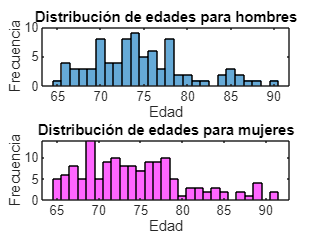

grupo_hombres = datos(datos.gender == 1, :);
grupo_mujeres = datos(datos.gender == 2, :);
edad_hombres = grupo_hombres.age;
edad_mujeres = grupo_mujeres.age;

% Crear histogramas para la variable 'age' en cada grupo
figure;
subplot(2,1,1);
histogram(edad_hombres);
title('Distribución de edades para hombres');
xlabel('Edad');
ylabel('Frecuencia');

subplot(2,1,2);
histogram(edad_mujeres, 'FaceColor', 'm');
title('Distribución de edades para mujeres');
xlabel('Edad');
ylabel('Frecuencia');

Otro punto de vista:

Se hace un análisis de correlación entre ‘*height*’ y ‘*weight*’. Un gráfico de dispersión es una buena opción para visualizar la relación entre estas dos variables.

Cada punto en el gráfico representa una observación en el conjunto de datos. La posición de cada punto en el eje x e y corresponde a su valor de ‘*height*’ y ‘*weight*’, respectivamente.

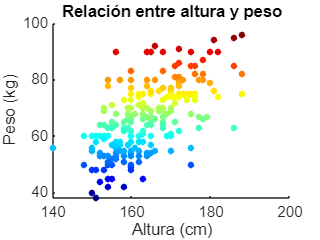

% Extraer las variables de interés
altura = datos.height;
peso = datos.weight;

% Crear un gráfico de dispersión
figure;
scatter(altura, peso, 15, peso, 'filled');
colormap(jet); % Crea un degradado de colores tipo arcoiris (estético)
title('Relación entre altura y peso');
xlabel('Altura (cm)');
ylabel('Peso (kg)');

El gráfico de dispersión muestra una tendencia donde los puntos se agrupan a lo largo de una línea recta con pendiente positiva, pero no es muy pronunciada. Se puede concluir que existe una correlación positiva entre las dos variables. En este caso, indica que a medida que la altura aumenta, el peso también tiende a aumentar.

Aunque la correlación es positiva, no es perfectamente fuerte (la agrupación de puntos no sigue una línea recta perfecta), lo que indica que hay una cantidad significativa de variabilidad en los datos. Esto significa que, aunque en general las personas más altas tienden a pesar más, hay muchas excepciones a esta tendencia.

       ** 2. Realizar la matriz de correlación y el análisis de varianza entre todas las variables**

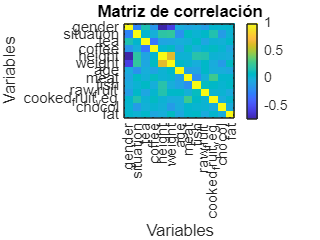

matriz_correlacion = corrcoef(table2array(datos));

% Visualizar la matriz de correlación
figure;
imagesc(matriz_correlacion);
colorbar; % Agrega una barra de colores para indicar los valores de correlación
title('Matriz de correlación');
xlabel('Variables');
ylabel('Variables');

% Etiquetas de los ejes x e y
xticks(1:length(datos.Properties.VariableNames));
xticklabels(datos.Properties.VariableNames);
xtickangle(90); % Rotar las etiquetas 90 grados
yticks(1:length(datos.Properties.VariableNames));
yticklabels(datos.Properties.VariableNames);

En el bloque anterior, `imagesc(matriz_correlacion)` crea una representación visual de la matriz de correlación. Los colores de los elementos de la matriz indican los valores de correlación, con una barra de colores a la derecha que indica qué colores corresponden a qué valores de correlación.

la ***covarianza*** se utiliza para medir la relación unicamnente  entre dos variables y cómo varían juntas. La covarianza puede ser útil para comprender la dirección y la fuerza de la relación entre dos variables en un conjunto de datos multivariado.

es una medida que indica cómo varían dos variables juntas. Mide la relación lineal entre dos variables.

frecuencia_male = sum(datos == 1);
frecuencia_female = sum(datos == 2);

% Crear una tabla de frecuencias
tabla_frecuencias = table({'Male'; 'Female'}, [frecuencia_male; frecuencia_female], 'VariableNames', {'Gender', 'Frequency'});

% Visualizar la tabla de frecuencias
disp('Tabla de Frecuencias para la Variable "Gender" con respecto a todas las variables:')

Tabla de Frecuencias para la Variable "Gender" con respecto a todas las variables:


disp(tabla_frecuencias)

      Gender                                                                  Frequency                                                            
    __________    _________________________________________________________________________________________________________________________________

                  gender    situation    tea    coffee    height    weight    age    meat    fish    raw_fruit    cooked_fruit_veg    chocol    fat
                  ______    _________    ___    ______    ______    ______    ___    ____    ____    ____


% Seleccionar las dos variables de interés
variable1 = datos.gender;
variable2 = datos.age;

% Calcular la covarianza entre las dos variables
covarianza = cov(variable1, variable2);

% Mostrar la covarianza
disp(covarianza);

    0.2357   -0.0861
   -0.0861   36.0640



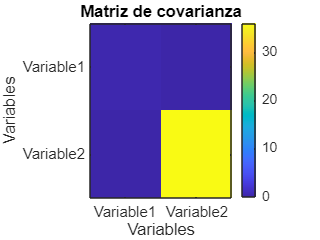


% Supongamos que tienes la matriz de covarianza calculada previamente llamada 'covarianza'

% Visualizar la matriz de covarianza como un mapa de calor
figure;
imagesc(covarianza);
colorbar; % Agrega una barra de colores para indicar los valores de covarianza
title('Matriz de covarianza');
xlabel('Variables');
ylabel('Variables');

% Etiquetas de los ejes x e y
xticks(1:length(covarianza));
yticks(1:length(covarianza));
xticklabels({'Variable1', 'Variable2'});
yticklabels({'Variable1', 'Variable2'}); 

### Parte 4 - Análisis final y conclusiones

- **Establecer conclusiones por cada uno de los análisis realizados en los parámetros  anteriores y por cada variable analizada. Es útil plantearse preguntas estadísticas para  concluir sobre el conjunto de datos, un ejemplo de esas preguntas se presenta a  continuación:**

Basado en los resultados del análisis de varianza (ANOVA), se pueden sacar varias conclusiones interesantes sobre las diferencias entre hombres y mujeres en la muestra de adultos mayores:

- **Situación social**: Los hombres tienden a vivir con su cónyuge, mientras que las mujeres tienen una situación social más variada, con una concentración en ser solteras.

- **Consumo de té y café**: Ambos géneros tienden a no tomar té, pero los hombres beben en promedio más tazas de café que las mujeres.

- **Altura y peso**: En promedio, los hombres de la muestra son más altos y pesan más que las mujeres.

- **Edad**: La edad de ambos grupos es extremadamente similar.

- **Dieta**: Los hombres tienden a comer carne más frecuentemente que las mujeres, mientras que el consumo de pescado es igual en ambos grupos. Los hombres tienden a comer más frutas crudas semanalmente que las mujeres, pero el consumo de frutas y verduras cocidas es prácticamente igual en ambos grupos.

- **Consumo de chocolate**: Las mujeres consumen, en promedio, más chocolate que los hombres.

- **Uso de aceite de girasol**: El uso de aceite de girasol es promedio en ambos grupos.

        **2. Si el análisis de datos se fuese a hacer público, ¿cuál sería el titular de la noticia que  pondrían para llamar la atención de los resultados?**

#### **Estudio revela: Los hombres mayores prefieren el café y la compañía, las mujeres mayores eligen el chocolate y la soltería**